% AAE 421 HW 4 Problem 4
% Tomoki Koike
close all; clear all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\hw4";
addpath(genpath("C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\rootlocus"));

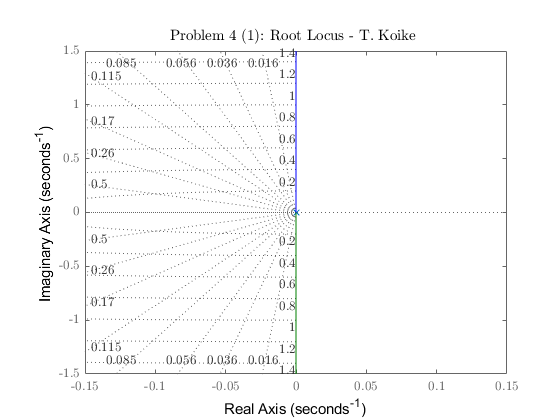

% (1)

% Define parameters
l = 1;
J = 100;
Kp = 1;
Krg = 1;
init = -rand(1);

G = tf([0, l], [J, 0, 0]);
% Plot
fig1 = figure(1);
    rlocus(G)
    title('Problem 4 (1): Root Locus - T. Koike ','interpreter','Latex')
    sgrid
saveas(fig1, fullfile(fdir, 'p4-1_RL.png'));

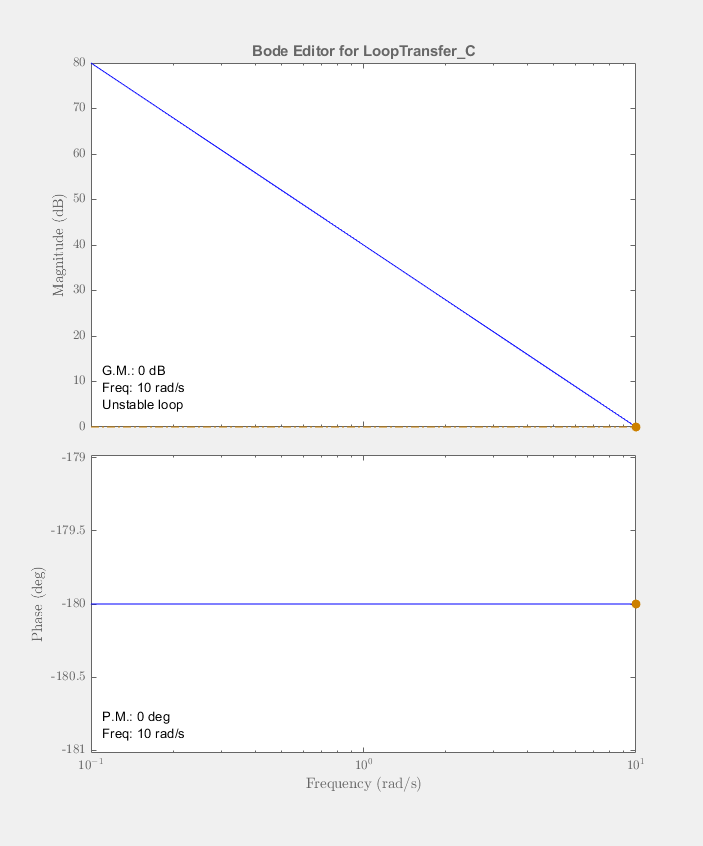

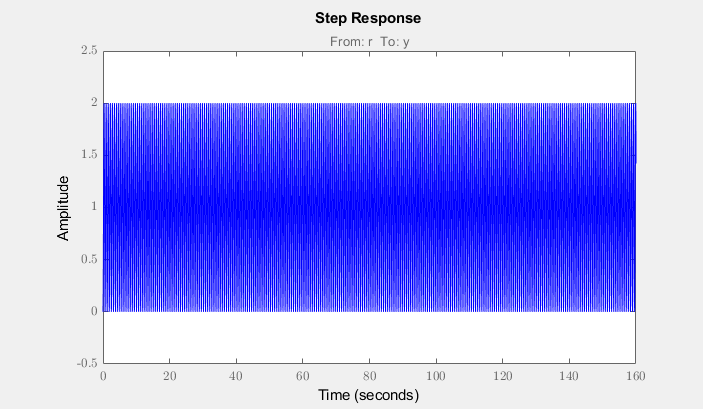

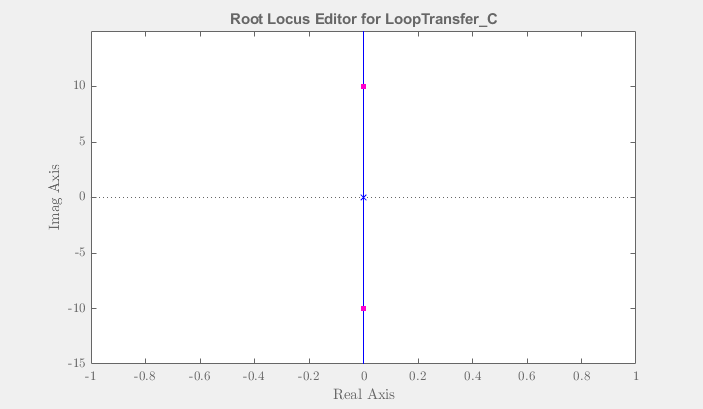

% (2)
l_J = 100;
Kp = 1;
Krg = 1;
% Define parameters
G = tf([0, l_J], [1, 0, 0]);
C2 = tf([Krg, 0], [0, 1]);
controlSystemDesigner(G)